%rpiを削除
clear rpi 

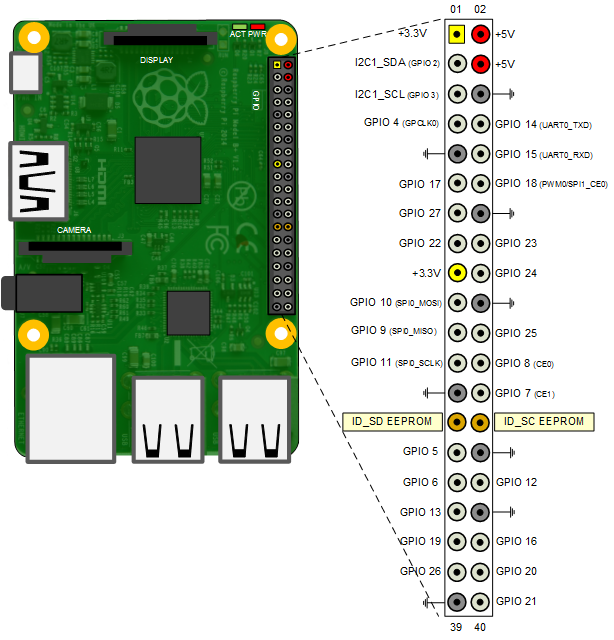

%rpi接続設定
%家用
%rpi = raspi('192.168.0.53', 'pi', 'milkyway');
%大学用
rpi = raspi('10.24.77.202', 'pi', 'milkyway'); 
writeDigitalPin(rpi, 26,1);

M_pin = 18;
B_pin = 26;
configurePin(rpi,M_pin,'DigitalInput')

ans = 'DigitalInput'

N = 100;
delay = 0.1;
for i = 1:N
    motionDetected = readDigitalPin(rpi,M_pin);
    if motionDetected
       writeDigitalPin(rpi, 26,0);
    else
       writeDigitalPin(rpi, 26,1);
    end
    pause(delay);
end
writeDigitalPin(rpi, 26,1);

%rpiを削除
clear rpi